%%%%%%%%%%%%%%%%%%%%%%
%%%timelines of measurement periods and operational periods
%%%created:1/5/22
%%%%%%%%%%%%%%%%%%%%%%

%% find current working folder
fp = fileparts(matlab.desktop.editor.getActiveFilename);
cd(fp) %% change to code folder
cd ../../Data/Processed/EtO/'Data Conversions' %change to data folder

%%canister data
%SDK
ppbSDKATEC = readtimetable("ppb SDK.xlsx", "Sheet", "ATEC", "VariableNamingRule", "preserve");
ppbSDKEnt = readtimetable("ppb SDK.xlsx", "Sheet", "Ent", "VariableNamingRule", "preserve");
ppbSDKPicarro = readtimetable("ppb SDK.xlsx", "Sheet", "Picarro", "VariableNamingRule", "preserve");

%STER
ppbSTER = readtimetable("ppb STER.xlsx", "Sheet", "base", "VariableNamingRule", "preserve");

%SSG
ppbSSG = readtimetable("ppb SSG.xlsx", "Sheet", "base", "VariableNamingRule", "preserve");

%COV
ppbCOV = readtimetable("ppb COV.xlsx", "Sheet", "base", "VariableNamingRule", "preserve");

cd ..
%SDK, AROMA
ppbAROMA = readtimetable("etoAROMA_SDK.xlsx");
cd ../.. %return to data folder

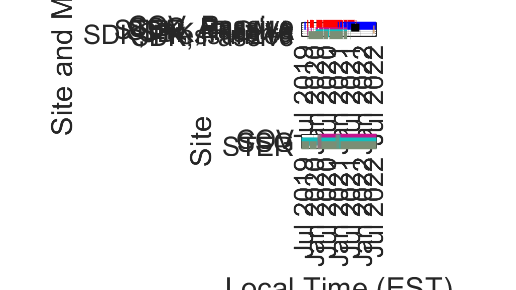

%%%%%%%%%%%%%%%%%%%%%%
%%% plot timelines of data recording
%%%%%%%%%%%%%%%%%%%%%%

%% inputs
colorSTER = [0.769, 0.080, 0.557];
colorSSG = [0.071, 0.74, 0.74];
colorCOV = [122, 142, 117]/255;
colorAROMA = [0.8392, 0.5686, 0.3098];
colors = [1, 0, 0; 0, 0, 1; 0, 0, 0; colorAROMA; colorSTER; colorSSG; colorCOV];
controlsSTER = datetime(2020, 4, 8);
controlsSSG = datetime(2021, 1, 26);
controlsCOV = datetime(2020, 3, 31);
xlims = datetime([2019, 2022], [7, 9], 1);
xtickss = xlims(1):calmonths(6):datetime(2022, 7, 1);

fig = figure('Position', get(0, 'Screensize')); %for saving the figure
tiledlayout(2, 1, "TileSpacing", "compact")

%%plot
ax = nexttile;
hold on
grid on
box on

%SDK, passive
temp = timetable2array(ppbSDKEnt); % extract data
valid = sum(any(~isnan(temp), 2), 2); % find days that are not nan
valid(valid == 0) = nan; %set invalid to nan
plot(ppbSDKEnt.Properties.RowTimes, ...
    7*valid, '-', 'LineWidth', 6, 'Color', colors(1, :));

%SDK, pressurized
temp = timetable2array(ppbSDKATEC); % extract data
valid = sum(any(~isnan(temp), 2), 2); % find days that are not nan
valid(valid == 0) = nan; %set invalid to nan
plot(ppbSDKATEC.Properties.RowTimes, ...
    6*valid, '-', 'LineWidth', 6, 'Color', colors(2, :));

%SDK, Picarro
plot([ppbSDKPicarro.time(1), ppbSDKPicarro.time(end)], ...
    5*ones(2), '-', 'LineWidth', 6, 'Color', colors(3, :));

%SDK, AROMA
plot([ppbAROMA.Properties.RowTimes(1), ppbAROMA.Properties.RowTimes(end)], ...
    4*ones(2), '-', 'LineWidth', 6, 'Color', colors(4, :));

%STER, passive
temp = timetable2array(ppbSTER); % extract data
valid = sum(any(~isnan(temp), 2), 2); % find days that are not nan
valid(valid == 0) = nan; %set invalid to nan
plot(ppbSTER.Properties.RowTimes, ...
    3*valid, '-', 'LineWidth', 6, 'Color', colors(5, :));

%SSG, passive
temp = timetable2array(ppbSSG); % extract data
valid = sum(any(~isnan(temp), 2), 2); % find days that are not nan
valid(valid == 0) = nan; %set invalid to nan
plot(ppbSSG.Properties.RowTimes, ...
    2*valid, '-', 'LineWidth', 6, 'Color', colors(6, :));

%COV, passive
temp = timetable2array(ppbCOV); % extract data
valid = sum(any(~isnan(temp), 2), 2); % find days that are not nan
valid(valid == 0) = nan; %set invalid to nan
plot(ppbCOV.Properties.RowTimes, ...
    1*valid, '-', 'LineWidth', 6, 'Color', colors(7, :));

xlim(xlims)
xticks(xtickss)
ylim([0, 8])
yticks(1:7)

pbaspect([5, 1, 1])
ax.FontSize = 20;
ax.YTickLabel = {'SDK, Passive', 'SDK, Pressurized', 'SDK, Picarro', 'SDK, AROMA', ...
    'STER, Passive', 'SSG, Passive', 'COV, Passive'};

ylabel('Site and Method')

hold off

ax = nexttile;
hold on
grid on
box on

%STER
plot(datetime([2020, 2030], 4, 8), ...
    3*ones(2), '-', 'LineWidth', 6, 'Color', colors(5, :));

%SSG
plot(datetime([2010, 2030], 4, 8), ...
    2*ones(2), '-', 'LineWidth', 6, 'Color', colors(6, :));

shutdownCOV = datetime([2019, 2019, 2020, 2020], ...
    [10, 11, 2, 3], ...
    [30, 8, 22, 2]);

%COV
plot(datetime([2010, 2019, 2019, 2019, 2020, 2020, 2020, 2030], ...
    [1, 10, 11, 11, 2, 2, 3, 1], [1, 30, 2, 8, 22, 25, 2, 1]), ...
    [1, 1, nan, 1, 1, nan, 1, 1], '-', 'LineWidth', 6, 'Color', colors(7, :));

xlim(xlims)
xticks(xtickss)
ylim([0, 4])
yticks(1:3)

pbaspect([5, 1, 1])
ax.FontSize = 20;
ax.YTickLabel = {'STER', 'SSG', 'COV'};
xlabel('Local Time (EST)')
ylabel('Site')

%controls lines
xline(controlsSTER, '--', "linewidth", 3, ...
    "color", colorSTER) %STER
xline(controlsSSG, '--', "linewidth", 3, ...
    "color", colorSSG) %SSG
xline(controlsCOV, '--', "linewidth", 3, ...
    "color", colorCOV) %COV
xline(datetime(2020, 12, 31), '--', "linewidth", 3, ...
    "color", colorCOV) %COV warehouse

hold off

% %%export the figure
% cd ..\Figures
% a = annotation('rectangle',[0 0 1 1],'Color','w'); %add padding
% fn = "Sup timelines.png";
% exportgraphics(fig, fn)
% delete(a) %make plot interactive again

% cd ..\Data